clc;clear;
score = zeros(4,2,6);

% 获取绘图值的代码块
load("EEI_DATA_100_200_1000.mat");
% EEIX_1 = EEI_DATA.x;
EEIY_1 = EEI_DATA.y(1:220,:);
EEI_DATA.y = EEI_DATA.y(1:220,:);
load("ParEGO_DATA_100_200_1000.mat");
PARX_1 = ParEGO_DATA.x(1:220,:);
PARY_1 = ParEGO_DATA.y(1:220,:);
ParEGO_DATA.y = ParEGO_DATA.y(1:220,:);
n = size(PARX_1,1);
minValEEI = zeros(n,3);
minValPAR = zeros(n,3);
HV1 = cal_hv(EEI_DATA);

20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200
201
202
203
204
205
206
207
208
209
210
211
212
213
214
215
216
217
218
219
220


HV2 = cal_hv(ParEGO_DATA);

20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200
201
202
203
204
205
206
207
208
209
210
211
212
213
214
215
216
217
218
219
220


% 赋值
i = 6

i = 6

score(1,1,i) = min(EEIY_1(:,1));
score(2,1,i) = min(EEIY_1(:,2));
score(3,1,i) = min(EEIY_1(:,3));
score(4,1,i) = HV1(1,201);
score(1,2,i) = min(PARY_1(:,1));
score(2,2,i) = min(PARY_1(:,2));
score(3,2,i) = min(PARY_1(:,3));
score(4,2,i) = HV2(1,201);

% 检查数据
save("score_plt","score")

% 加载数据绘图
clc;clear;
load("score_plt")

c = ['#A43546';'#1A5276';'#963CC2';'#4E9E35';'#AAAC4D';'#26F1F1'];

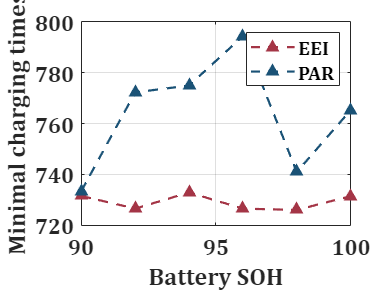

close(figure(1));
figure(1);
it = 90:2:100;
p1 = plot(it,reshape(score(1,1,:),[1,6]),'^--',...
    'Color',c(1,:),'LineWidth',1.5,'MarkerSize',6,'MarkerFaceColor',c(1,:));
hold on
p2 = plot(it,reshape(score(1,2,:),[1,6]),'^--',...
    'Color',c(2,:),'LineWidth',1.5,'MarkerSize',6,'MarkerFaceColor',c(2,:));

grid on
legend([p1,p2],["EEI","PAR"]);
xlabel('Battery SOH');
ylabel('Minimal charging times');
set(gca,'fontname','Cambria','fontsize',15,'FontWeight','bold');

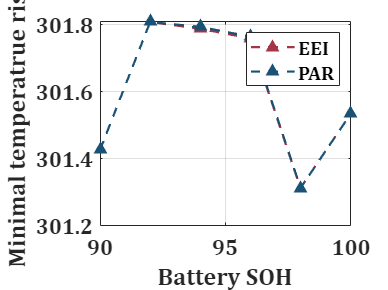

close(figure(1));
figure(1);
it = 90:2:100;
p1 = plot(it,reshape(score(2,1,:),[1,6]),'^--',...
    'Color',c(1,:),'LineWidth',1.5,'MarkerSize',6,'MarkerFaceColor',c(1,:));
hold on
p2 = plot(it,reshape(score(2,2,:),[1,6]),'^--',...
    'Color',c(2,:),'LineWidth',1.5,'MarkerSize',6,'MarkerFaceColor',c(2,:));

grid on
legend([p1,p2],["EEI","PAR"]);
xlabel('Battery SOH');
ylabel('Minimal temperatrue rise');
set(gca,'fontname','Cambria','fontsize',15,'FontWeight','bold');

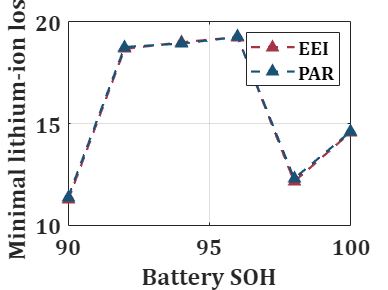

close(figure(1));
figure(1);
it = 90:2:100;
p1 = plot(it,reshape(score(3,1,:),[1,6]),'^--',...
    'Color',c(1,:),'LineWidth',1.5,'MarkerSize',6,'MarkerFaceColor',c(1,:));
hold on
p2 = plot(it,reshape(score(3,2,:),[1,6]),'^--',...
    'Color',c(2,:),'LineWidth',1.5,'MarkerSize',6,'MarkerFaceColor',c(2,:));

grid on
legend([p1,p2],["EEI","PAR"]);
xlabel('Battery SOH');
ylabel('Minimal lithium-ion loss');
set(gca,'fontname','Cambria','fontsize',15,'FontWeight','bold');

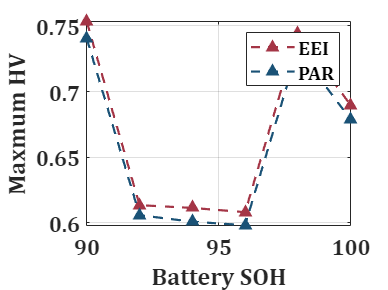

close(figure(1));
figure(1);
it = 90:2:100;
p1 = plot(it,reshape(score(4,1,:),[1,6]),'^--',...
    'Color',c(1,:),'LineWidth',1.5,'MarkerSize',6,'MarkerFaceColor',c(1,:));
hold on
p2 = plot(it,reshape(score(4,2,:),[1,6]),'^--',...
    'Color',c(2,:),'LineWidth',1.5,'MarkerSize',6,'MarkerFaceColor',c(2,:));

grid on
legend([p1,p2],["EEI","PAR"]);
xlabel('Battery SOH');
ylabel('Maxmum HV');
set(gca,'fontname','Cambria','fontsize',15,'FontWeight','bold');

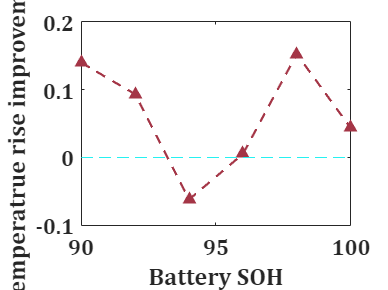

%补充一下提升量的曲线
close(figure(1));
figure(1);
it = 90:2:100;
p1 = plot(it,reshape(score(3,2,:),[1,6]) - reshape(score(3,1,:),[1,6]),'^--',...
    'Color',c(1,:),'LineWidth',1.5,'MarkerSize',6,'MarkerFaceColor',c(1,:));
hold on
p2 = plot(it,[0 0 0 0 0 0],'Color',c(6,:),LineStyle='--');
xlabel('Battery SOH');
ylabel('temperatrue rise improvements');
set(gca,'fontname','Cambria','fontsize',15,'FontWeight','bold');

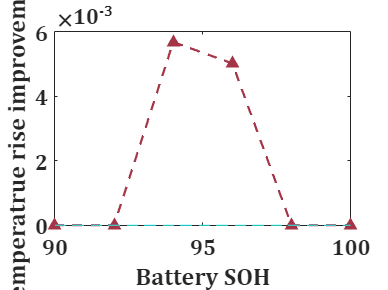

%补充一下提升量的曲线
close(figure(1));
figure(1);
it = 90:2:100;
p1 = plot(it,reshape(score(2,2,:),[1,6]) - reshape(score(2,1,:),[1,6]),'^--',...
    'Color',c(1,:),'LineWidth',1.5,'MarkerSize',6,'MarkerFaceColor',c(1,:));
hold on
p2 = plot(it,[0 0 0 0 0 0],'Color',c(6,:),LineStyle='--');
xlabel('Battery SOH');
ylabel('temperatrue rise improvements');
set(gca,'fontname','Cambria','fontsize',15,'FontWeight','bold');

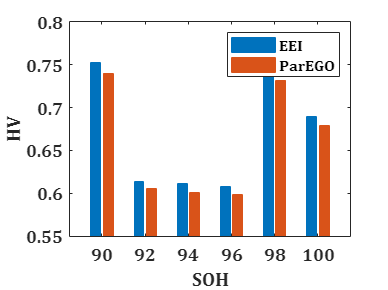

X = categorical({'90','92','94','96', '98', '100'});
X = reordercats(X,{'90','92','94','96', '98', '100'});
y = [score(4,:,1);score(4,:,2);score(4,:,3);score(4,:,4);score(4,:,5);score(4,:,6)];
close(figure(1));
figure(1);
b = bar(X,y,FaceColor="flat",EdgeColor="flat");
xlabel("SOH");
ylabel("HV");
ylim([0.55,0.8]);
legend("EEI","ParEGO");
set(gca,'fontname','Cambria','fontsize',12,'FontWeight','bold');

X = categorical({'ParEGO','EEI'});
X = reordercats(X,{'ParEGO','EEI'});
y = [score(4,:,1);score(4,:,2)];
close(figure(1));
figure(1);
b = bar(X,y,FaceColor="flat",EdgeColor="flat");
xlabel("SOH");
ylabel("HV");
ylim([0.55,0.8]);
legend("EEI","ParEGO");
set(gca,'fontname','Cambria','fontsize',12,'FontWeight','bold');